%% ============================================================
%  PRINCIPAL COMPONENT ANALYSIS (PCA) IN MATLAB
%  *** No toolboxes required – pure base MATLAB only ***
%  Covers: Theory, From-Scratch PCA, Manual pca() replacement,
%          2D/3D Visualisation, Image Compression, Denoising
%% ============================================================

clear; clc; close all;

%% ============================================================
%  LOCAL HELPER FUNCTIONS  (defined at bottom, called throughout)
%  my_pca(X)         – full PCA: scores, loadings, var_explained
%  gauss_data(mu, S, n) – correlated Gaussian samples via Cholesky
%% ============================================================


%% ============================================================
%  SECTION 1: PCA FROM SCRATCH – 2D CORRELATED DATA
%% ============================================================
fprintf('===== SECTION 1: PCA From Scratch =====\n\n');

===== SECTION 1: PCA From Scratch =====




% --- Generate correlated 2D data (no mvnrnd needed) ---
rng(42);
mu_1  = [3, 5];
Sigma = [3 2; 2 2];                        % Target covariance
X_raw = gauss_data(mu_1, Sigma, 200);      % 200 × 2, base MATLAB only

% Step 1 – Mean-centre
X_mean   = mean(X_raw);
X_center = X_raw - X_mean;

% Step 2 – Covariance matrix
n = size(X_center, 1);
C = (X_center' * X_center) / (n - 1);
fprintf('Covariance Matrix:\n'); disp(C);

Covariance Matrix:
    3.2760    2.0786
    2.0786    1.9838




% Step 3 – Eigendecomposition  (eig is base MATLAB)
[V, D]       = eig(C);
eigenvalues  = diag(D);
[eigenvalues, idx] = sort(eigenvalues, 'descend');
V            = V(:, idx);

fprintf('Eigenvalues (descending): %.4f, %.4f\n', eigenvalues(1), eigenvalues(2));

Eigenvalues (descending): 4.8067, 0.4532


fprintf('Eigenvectors (columns):\n'); disp(V);

Eigenvectors (columns):
   -0.8052    0.5930
   -0.5930   -0.8052




% Step 4 – Project
Z_scratch = X_center * V;         % 2D → 2D
Z_1D      = X_center * V(:,1);   % 2D → 1D (keep PC1 only)

% Step 5 – Variance explained
var_exp = eigenvalues / sum(eigenvalues) * 100;
fprintf('Variance Explained  PC1: %.2f%%\n', var_exp(1));

Variance Explained  PC1: 91.38%


fprintf('Variance Explained  PC2: %.2f%%\n\n', var_exp(2));

Variance Explained  PC2: 8.62%



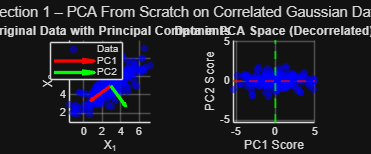


%% ---- Figure 1: Original data + PCs  vs  PCA space ----
figure('Name','PCA From Scratch','Position',[50 50 1200 500]);

subplot(1,2,1);
scatter(X_raw(:,1), X_raw(:,2), 30, 'b', 'filled', 'MarkerFaceAlpha', 0.5);
hold on;
sc = 3;
quiver(X_mean(1),X_mean(2), sc*V(1,1),sc*V(2,1),'r','LineWidth',2.5,'MaxHeadSize',0.5);
quiver(X_mean(1),X_mean(2), sc*V(1,2),sc*V(2,2),'g','LineWidth',2.5,'MaxHeadSize',0.5);
legend('Data','PC1','PC2','Location','best');
title('Original Data with Principal Components');
xlabel('X_1'); ylabel('X_2'); grid on; axis equal;

subplot(1,2,2);
scatter(Z_scratch(:,1), Z_scratch(:,2), 30, 'b', 'filled', 'MarkerFaceAlpha', 0.5);
hold on;
yline(0,'r--','LineWidth',1.5); xline(0,'g--','LineWidth',1.5);
title('Data in PCA Space (Decorrelated)');
xlabel('PC1 Score'); ylabel('PC2 Score'); grid on; axis equal;
sgtitle('Section 1 – PCA From Scratch on Correlated Gaussian Data');



%% ============================================================
%  SECTION 2: my_pca()  ON A 4-FEATURE (IRIS-LIKE) DATASET
%% ============================================================
fprintf('===== SECTION 2: my_pca() on 4D Iris-like Dataset =====\n\n');

===== SECTION 2: my_pca() on 4D Iris-like Dataset =====




rng(0);
n_per = 50;
% Three Gaussian clusters (4 features) – Cholesky-based, no mvnrnd
c1 = gauss_data([5.0 3.4 1.5 0.3], 0.15*eye(4), n_per);
c2 = gauss_data([5.9 2.8 4.2 1.3], 0.20*eye(4), n_per);
c3 = gauss_data([6.6 3.0 5.5 2.0], 0.25*eye(4), n_per);
X_iris  = [c1; c2; c3];
labels  = [ones(n_per,1); 2*ones(n_per,1); 3*ones(n_per,1)];

[score_i, coeff_i, var_exp_i] = my_pca(X_iris);

fprintf('PC Loadings:\n');         disp(coeff_i);

PC Loadings:
    0.3165    0.4212    0.8366   -0.1502
   -0.1053    0.7811   -0.2527    0.5612
    0.8715   -0.2246   -0.1426    0.4120
    0.3596    0.4025   -0.4647   -0.7020



fprintf('Variance Explained (%%): ');

Variance Explained (%): 

fprintf('%.2f  ', var_exp_i);      fprintf('\n');

86.32  5.23  4.55  3.91  


fprintf('Cumulative (first 2 PCs): %.2f%%\n\n', sum(var_exp_i(1:2)));

Cumulative (first 2 PCs): 91.55%



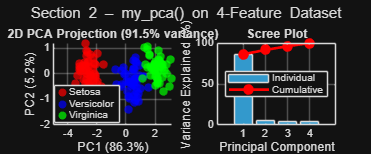


%% ---- Figure 2: 2D scatter + scree plot ----
figure('Name','my_pca – Iris-like','Position',[50 50 1200 500]);
clrs = {'r','b','g'};
cnames = {'Setosa','Versicolor','Virginica'};

subplot(1,2,1); hold on;
for c = 1:3
    mk = labels == c;
    scatter(score_i(mk,1), score_i(mk,2), 40, clrs{c}, 'filled', 'MarkerFaceAlpha', 0.7);
end
legend(cnames,'Location','best');
title(sprintf('2D PCA Projection (%.1f%% variance)', sum(var_exp_i(1:2))));
xlabel(sprintf('PC1 (%.1f%%)', var_exp_i(1)));
ylabel(sprintf('PC2 (%.1f%%)', var_exp_i(2)));
grid on;

subplot(1,2,2);
bar(var_exp_i(1:4), 'FaceColor', [0.2 0.6 0.8]); hold on;
plot(cumsum(var_exp_i(1:4)), 'r-o', 'LineWidth', 2, 'MarkerFaceColor','r');
xticks(1:4); xlabel('Principal Component');
ylabel('Variance Explained (%)'); title('Scree Plot');
legend('Individual','Cumulative','Location','best'); grid on;
sgtitle('Section 2 – my\_pca() on 4-Feature Dataset');



%% ============================================================
%  SECTION 3: 3D → 2D DIMENSIONALITY REDUCTION
%% ============================================================
fprintf('===== SECTION 3: 3D → 2D Dimensionality Reduction =====\n\n');

===== SECTION 3: 3D → 2D Dimensionality Reduction =====




rng(7);
t    = linspace(0, 4*pi, 300);
X_3D = [cos(t); sin(t); 0.5*t]' + 0.15*randn(300,3);

[score3, ~, var_exp3] = my_pca(X_3D);
fprintf('Variance Explained (3D): %.2f%%  %.2f%%  %.2f%%\n\n', ...
        var_exp3(1), var_exp3(2), var_exp3(3));

Variance Explained (3D): 78.64%  11.51%  9.85%



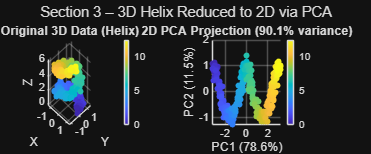


figure('Name','3D to 2D PCA','Position',[50 50 1200 500]);

subplot(1,2,1);
scatter3(X_3D(:,1), X_3D(:,2), X_3D(:,3), 20, t, 'filled');
colorbar; title('Original 3D Data (Helix)');
xlabel('X'); ylabel('Y'); zlabel('Z'); grid on; view(45,30);

subplot(1,2,2);
scatter(score3(:,1), score3(:,2), 20, t, 'filled');
colorbar;
title(sprintf('2D PCA Projection (%.1f%% variance)', sum(var_exp3(1:2))));
xlabel(sprintf('PC1 (%.1f%%)', var_exp3(1)));
ylabel(sprintf('PC2 (%.1f%%)', var_exp3(2)));
grid on;
sgtitle('Section 3 – 3D Helix Reduced to 2D via PCA');



%% ============================================================
%  SECTION 4: IMAGE COMPRESSION  (Eigenfaces-style)
%% ============================================================
fprintf('===== SECTION 4: Image Compression via PCA =====\n\n');

===== SECTION 4: Image Compression via PCA =====



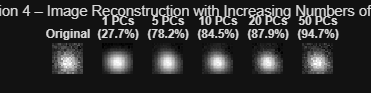


rng(3);
img_h = 20; img_w = 20; n_img = 100;
[xx, yy] = meshgrid(linspace(-1,1,img_w), linspace(-1,1,img_h));

X_faces = zeros(n_img, img_h*img_w);
for i = 1:n_img
    cx   = 0.3*randn;  cy = 0.3*randn;
    r    = 0.5 + 0.1*randn;
    face = exp(-((xx-cx).^2 + (yy-cy).^2) / (2*r^2));
    face = face + 0.1*randn(img_h, img_w);
    X_faces(i,:) = face(:)';
end

[score_f, coeff_f, var_exp_f] = my_pca(X_faces);
mu_faces = mean(X_faces);          % row-mean needed for reconstruction

n_pcs_list = [1, 5, 10, 20, 50];
sidx = 1;                          % sample image to reconstruct

figure('Name','Image Compression via PCA','Position',[50 50 1400 350]);
subplot(1, numel(n_pcs_list)+1, 1);
imagesc(reshape(X_faces(sidx,:), img_h, img_w));
colormap gray; axis image off; title('Original');

for k = 1:numel(n_pcs_list)
    nk    = n_pcs_list(k);
    recon = score_f(sidx,1:nk) * coeff_f(:,1:nk)' + mu_faces;
    subplot(1, numel(n_pcs_list)+1, k+1);
    imagesc(reshape(recon, img_h, img_w));
    axis image off;
    title(sprintf('%d PCs\n(%.1f%%)', nk, sum(var_exp_f(1:nk))));
end
sgtitle('Section 4 – Image Reconstruction with Increasing Numbers of PCs');



%% ============================================================
%  SECTION 5: SIGNAL DENOISING VIA PCA
%% ============================================================
fprintf('===== SECTION 5: PCA Signal Denoising =====\n\n');

===== SECTION 5: PCA Signal Denoising =====




rng(5);
t_sig  = linspace(0, 2*pi, 50);
n_sig  = 80;
signal = sin(t_sig);

X_noisy = repmat(signal, n_sig, 1) + 0.8*randn(n_sig, numel(t_sig));

[score_s, coeff_s, var_exp_s] = my_pca(X_noisy);
mu_noisy = mean(X_noisy);
fprintf('Variance in PC1 (signal): %.1f%%\n\n', var_exp_s(1));

Variance in PC1 (signal): 6.1%



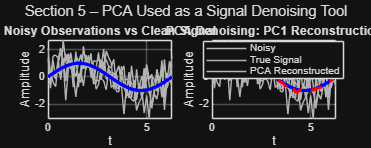


% Reconstruct with PC1 only
recon_sig = score_s(:,1) * coeff_s(:,1)' + mu_noisy;

figure('Name','PCA Denoising','Position',[50 50 1000 400]);

subplot(1,2,1);
plot(t_sig, X_noisy(1:5,:)', 'Color',[0.7 0.7 0.7]); hold on;
plot(t_sig, signal, 'b', 'LineWidth', 2.5);
title('Noisy Observations vs Clean Signal');
xlabel('t'); ylabel('Amplitude'); grid on;

subplot(1,2,2);
plot(t_sig, X_noisy(1:5,:)', 'Color',[0.7 0.7 0.7]); hold on;
plot(t_sig, signal,          'b',  'LineWidth', 2.5);
plot(t_sig, recon_sig(1,:),  'r--','LineWidth', 2);
legend('Noisy','True Signal','PCA Reconstructed','Location','best');
title('PCA Denoising: PC1 Reconstruction');
xlabel('t'); ylabel('Amplitude'); grid on;
sgtitle('Section 5 – PCA Used as a Signal Denoising Tool');


fprintf('\n===== All sections complete. Check Figure windows. =====\n');


===== All sections complete. Check Figure windows. =====




%% ============================================================
%  LOCAL FUNCTION: my_pca  (replaces built-in pca())
%  Works on any n×p matrix. Uses only eig() – base MATLAB.
%% ============================================================
function [scores, loadings, var_explained] = my_pca(X)
% MY_PCA  Full PCA using base MATLAB only (no toolboxes).
%
%   [scores, loadings, var_explained] = my_pca(X)
%
%   X            – n×p data matrix  (observations × features)
%   scores       – n×p projected coordinates in PC space
%   loadings     – p×p matrix; columns are principal components
%   var_explained– p×1 vector of % variance per component

    X_c = X - mean(X);                        % Mean-centre
    C   = (X_c' * X_c) / (size(X,1) - 1);    % p×p covariance

    [V, D]    = eig(C);                        % base MATLAB eig()
    ev        = diag(D);
    [ev, idx] = sort(ev, 'descend');           % descending order
    V         = V(:, idx);

    scores       = X_c * V;
    loadings     = V;
    var_explained = ev / sum(ev) * 100;
end


%% ============================================================
%  LOCAL FUNCTION: gauss_data  (replaces mvnrnd())
%  Generates n samples from N(mu, Sigma) via Cholesky decomp.
%% ============================================================
function X = gauss_data(mu, Sigma, n)
% GAUSS_DATA  Multivariate Gaussian samples – base MATLAB only.
%
%   X = gauss_data(mu, Sigma, n)
%
%   mu    – 1×p mean vector
%   Sigma – p×p positive-definite covariance matrix
%   n     – number of samples
%   X     – n×p sample matrix

    p = numel(mu);
    L = chol(Sigma, 'lower');                  % Cholesky: Sigma = L*L'
    Z = randn(n, p);                           % Standard normal samples
    X = Z * L' + mu;                           % Affine transform
end